# Transform Road Image to Bird's-Eye-View Image

Create a bird's-eye-view image from an image obtained by a front-facing camera mounted on a vehicle. Display points within the bird's-eye view using the vehicle and image coordinate systems.

Define the camera intrinsics and create an object containing these intrinsics.

clear all;
focalLength = [1.0398e+03 1.0384e+03];
principalPoint = [963.3056 561.9757];
imageSize = [1080 1920];

camIntrinsics = cameraIntrinsics(focalLength,principalPoint,imageSize);

Set the height of the camera to be about 2 meters above the ground. Set the pitch of the camera to 14 degrees toward the ground.

height = 1.4;
pitch = 0;

Create an object containing the camera configuration.

sensor = monoCamera(camIntrinsics,height,'Pitch',pitch);

Define the area in front of the camera that you want to transform into a bird's-eye view. Set an area from 3 to 30 meters in front of the camera, with 6 meters to either side of the camera.

distAhead = 5;
spaceToOneSide = 1;
bottomOffset = 1;

outView = [bottomOffset,distAhead,-spaceToOneSide,spaceToOneSide];

Set the output image width to 250 pixels. Compute the output length automatically from the width by setting the length to `NaN`.

outImageSize = [NaN,250];

Create an object for performing bird's-eye-view transforms, using the previously defined parameters.

birdsEye = birdsEyeView(sensor,outView,outImageSize);

Load an image that was captured by the sensor.

cam = webcam(2)

cam =   webcam with properties:

                    Name: 'Logitech Webcam C930e'
    AvailableResolutions: {'1920x1080'}
              Resolution: '1920x1080'


I = snapshot(cam);

Transform the input image into a bird's-eye-view image.

BEV = transformImage(birdsEye,I);

In the bird's-eye-view image, place a 20-meter marker directly in front of the sensor. Use the `vehicleToImage` function to specify the location of the marker in vehicle coordinates. Display the marker on the bird's-eye-view image.

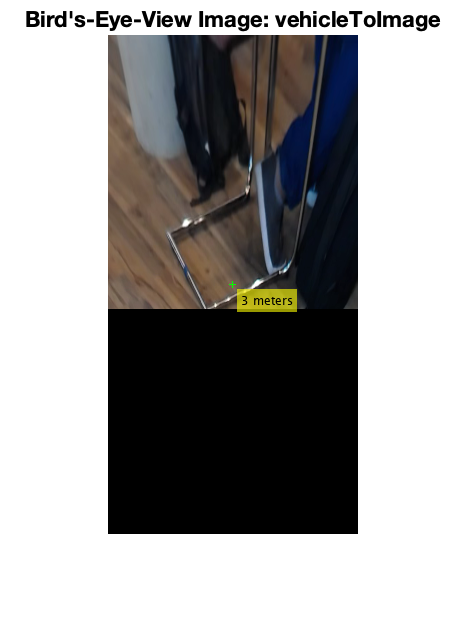

imagePoint = vehicleToImage(birdsEye,[3 0]);
annotatedBEV = insertMarker(BEV,imagePoint);
annotatedBEV = insertText(annotatedBEV,imagePoint + 5,'3 meters');

figure
imshow(annotatedBEV)
title('Bird''s-Eye-View Image: vehicleToImage')

Define a location in the original bird's-eye-view image, this time in image coordinates. Use the `imageToVehicle` function to convert the image coordinates to vehicle coordinates. Display the distance between the marker and the front of the vehicle.

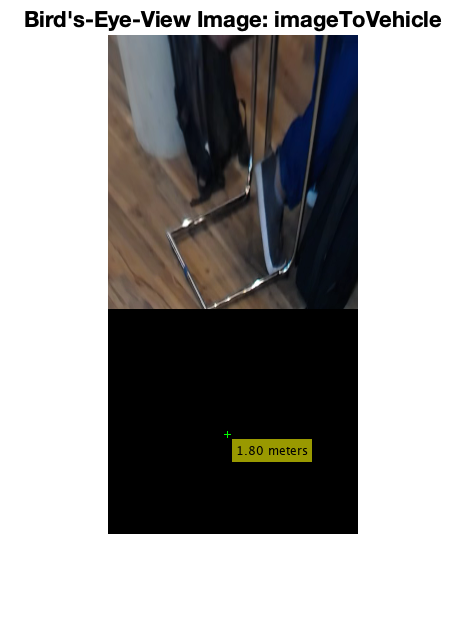

imagePoint2 = [120 400];
annotatedBEV = insertMarker(BEV,imagePoint2);

vehiclePoint = imageToVehicle(birdsEye,imagePoint2);
xAhead = vehiclePoint(1);
displayText = sprintf('%.2f meters',xAhead);
annotatedBEV = insertText(annotatedBEV,imagePoint2 + 5,displayText);

figure
imshow(annotatedBEV)
title('Bird''s-Eye-View Image: imageToVehicle')

*Copyright 2012 The MathWorks, Inc.*